# Projekt 1

### Zadanie 1:

clear;
disp('Zadanie 1:')

Zadanie 1:


symulacja_obiektu15Y_p1(1.2,1.2,2,2)

ans = 2

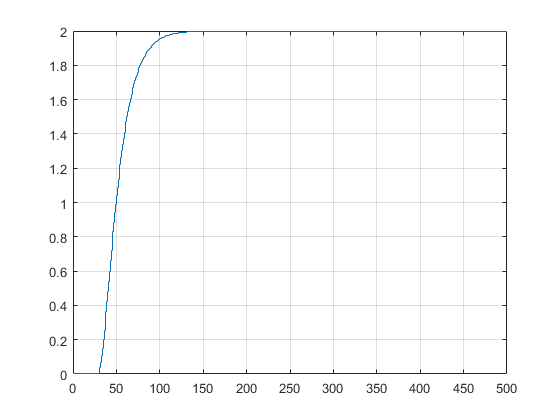

SIM_LENGHT = 500;
Upp = 1.2;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
U(:) = 1.2;
U(50:end) = 1.2;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
        U(k-11), Y(k-1), Y(k-2));
end
stairs(Y)
grid


writematrix(Y, 'p1_zadanie1.csv')

### Zadanie 2:

clear;
disp('Zadanie 2:')

Zadanie 2:


Wyznaczyć symulacyjnie odpowiedzi skokowe procesu dla kilku zmian sygnału sterującego, przy uwzględnieniu ograniczeń wartości tego sygnału, jego wartość na początku eksperymentu wynosi Upp.  Narysować te odpowiedzi na jednym rysunku.

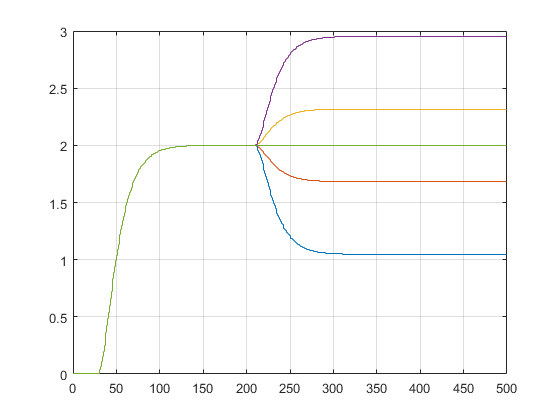

U_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
STEP_MOMENT = 200;
Upp = 1.2;
U(:) = Upp;


for p=1:length(U_zad_zmiany)
    U(200:end) = U_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
            U(k-11), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Narysować charakterystykę statyczną procesu y(u). Czy właściwości statyczne i dynamiczne procesu są (w przybliżeniu) liniowe? Jeżeli tak, określić wzmocnienie statyczne procesu.

disp('Charakterystyka statyczna:')

Charakterystyka statyczna:


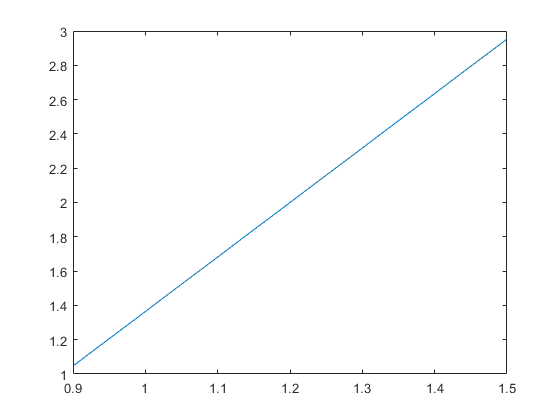

Y_stat = zeros(100,1);

U_zad = linspace(0.9, 1.5, 100)';
for i = 1:length(U_zad)
    [Y, U] = get_YU(1.2, U_zad(i), SIM_LENGHT, STEP_MOMENT);
    Y_stat(i)= Y(SIM_LENGHT);
end
plot(U_zad, Y_stat)

Wzmocnienie statyczne to wspolczynnik kierunkowy prostej z wykresu


x = U_zad(:);
y = Y_stat(:);
X = [x.^0, x];
b = (X'*X)\X'*y;
Wzm_stat = b(2)

Wzm_stat = 3.1778

### Zadanie 3:

Przekształcić jedną z otrzymanych odpowiedzi w taki sposób, aby otrzymać odpowiedź skokową wykorzystywaną w algorytmie DMC, tzn. zestaw liczb s1, s2, . . . (przy skoku jednostkowym sygnału sterującego: od chwili k = 0 włącznie sygnał sterujący ma wartość 1, w przeszłości jest zerowy). Zamieścić rysunek odpowiedzi skokowej

clear;
disp('Zadanie 3:')

Zadanie 3:


% symulacja_obiektu15Y_p1(0.9,0.9,1.047,1.047)
% symulacja_obiektu15Y_p1(1,1,1.047,1.047)

SIM_LENGHT = 500;
STEP_MOMENT = 300

STEP_MOMENT = 300

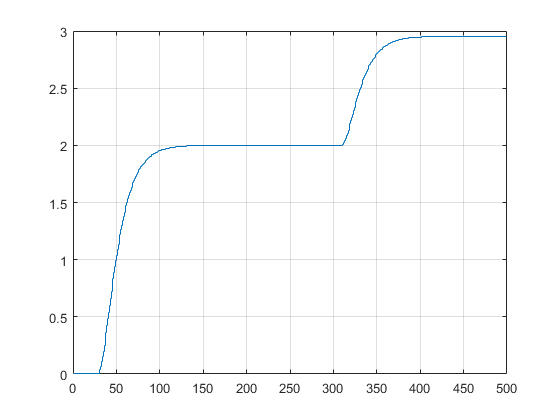

Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
U(:) = 1.2;
U(STEP_MOMENT:end) = 1.5;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
        U(k-11), Y(k-1), Y(k-2));
end
stairs(Y)
% hold on
% stairs(U, "--")
grid on

Przeksztalcenie odpowiedzi skokowej - to o czym mowil Ławryńczuk na drugich ćwiczeniach

Wektor s ze współczynnikami s1, s2, ...

deltaU = 1.5-1.2

deltaU = 0.3000

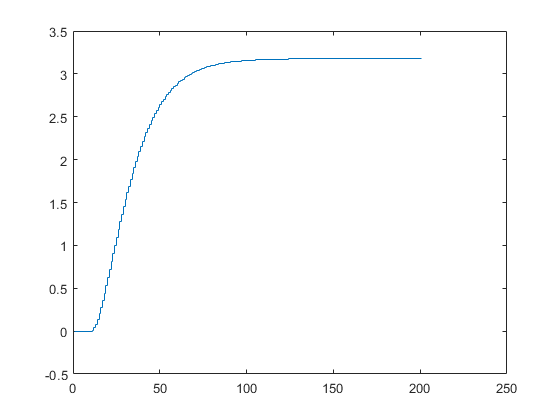


% U_przeksztalcone = U(STEP_MOMENT:end)
s = Y(STEP_MOMENT:end);
s = (s-2.0)/deltaU;

stairs(s)

Zadadnie 5


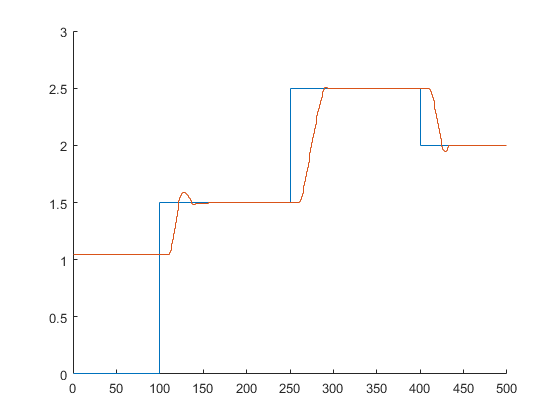

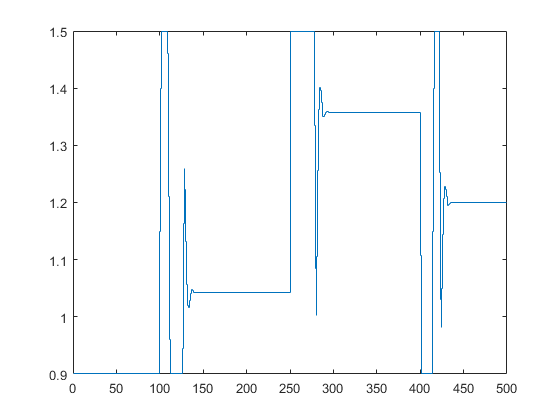

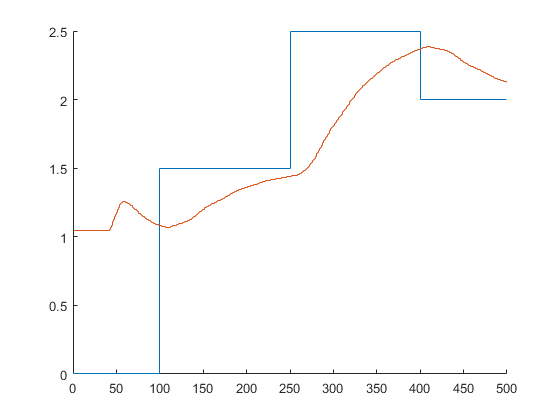

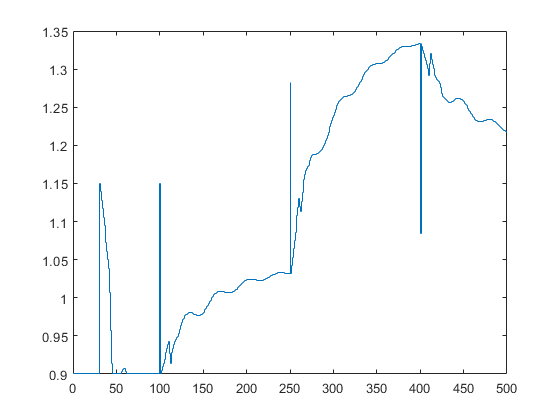

err = 11.6960

% hold on
% stairs(U_przeksztalcone)
save("model.mat","s");

#### FUNKCJE:

Funkcja Piotra do wyznaczania odpowiedzi skokowych

function [Y, U] = get_YU(U_pp, U_zad, sim_lenght, step_moment)
Y = zeros(sim_lenght,1);
U = zeros(sim_lenght,1);
U(:) = U_pp;
U(step_moment:end) = U_zad;
for k=30:sim_lenght
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), U(k-11), Y(k-1), Y(k-2));
end
end
